% =========================================================================
% FUNKCJE DO ANALIZY FILTRÓW W OBWODZIE SZEREGOWYM RLC
% =========================================================================

%% Funkcja główna: Obliczanie transmitancji dla wszystkich typów filtrów
function [wielkosc, faza, parametry] = analiza_filtra_RLC(R, L, C, w_czestotliwosci)
    % Funkcja oblicza moduł i fazę transmitancji dla filtrów RLC
    %
    % Parametry wejściowe: to bym zostawila bo spoko
    %   R - rezystancja [Ω]
    %   L - indukcyjność [H]
    %   C - pojemność [F]
    %   w_czestotliwosci - wektor częstotliwości [Hz]
    %
    % Parametry wyjściowe:
    %   wielkosc - struktura z modułami transmitancji [LP, HP, BP]
    %   faza - struktura z fazami transmitancji [LP, HP, BP] [stopnie]
    %   parametry - parametry charakterystyczne obwodu
    
    % Konwersja na pulsację kołową
    omega = 2 * pi * w_czestotliwosci;
    
    % Obliczanie parametrów charakterystycznych
    omega0 = 1 / sqrt(L * C);           % Częstotliwość rezonansowa [rad/s]
    f0 = omega0 / (2 * pi);             % Częstotliwość rezonansowa [Hz]
    Q = omega0 * L / R;                  % Dobroć obwodu
    szerokosc_pasma = R / L;                   % Szerokość pasma [rad/s]
    szerokosc_pasma_Hz = szerokosc_pasma / (2 * pi); % Szerokość pasma [Hz]
    
    % Zapisanie parametrów
    parametry.omega0 = omega0;
    parametry.f0 = f0;
    parametry.Q = Q;
    parametry.szerokosc_pasma = szerokosc_pasma;
    parametry.szerokosc_pasma_Hz = szerokosc_pasma_Hz;
    parametry.R = R;
    parametry.L = L;
    parametry.C = C;
    
    % Obliczanie transmitancji
    [H_LP, H_HP, H_BP] = obliczanie_transferu_funkcji(omega, R, L, C);
    
    % Moduły transmitancji
    wielkosc.LP = abs(H_LP);
    wielkosc.HP = abs(H_HP);
    wielkosc.BP = abs(H_BP);
    
    % Fazy transmitancji [stopnie]
    faza.LP = angle(H_LP) * 180 / pi;
    faza.HP = angle(H_HP) * 180 / pi;
    faza.BP = angle(H_BP) * 180 / pi;
end

%% Funkcja pomocnicza: Obliczanie transmitancji zespolonych
function [H_LP, H_HP, H_BP] = obliczanie_transferu_funkcji(omega, R, L, C)
    % Oblicza transmitancje zespolone dla trzech typów filtrów
    %
    % Parametry wejściowe:
    %   omega - wektor pulsacji kołowych [rad/s]
    %   R, L, C - parametry obwodu
    %
    % Parametry wyjściowe:
    %   H_LP, H_HP, H_BP - transmitancje zespolone
    
    % Wspólny mianownik dla wszystkich transmitancji
    denominator = 1 - omega.^2 * L * C + 1i * omega * R * C;
    
    % Filtr dolnoprzepustowy (kondensator)
    H_LP = 1 ./ denominator;
    
    % Filtr górnoprzepustowy (cewka)
    H_HP = (-omega.^2 * L * C) ./ denominator;
    
    % Filtr środkowoprzepustowy (rezystor)
    H_BP = (1i * omega * R * C) ./ denominator;
end

%% Funkcja do obliczania transmitancji w decybelach
function [mag_dB] = obliczanie_wielkosc_dB(wielkosc)
    % Konwertuje moduł transmitancji na decybele
    %
    % Parametry wejściowe:
    %   wielkosc - struktura z modułami transmitancji
    %
    % Parametry wyjściowe:
    %   mag_dB - struktura z modułami w decybelach
    
    mag_dB.LP = 20 * log10(wielkosc.LP);
    mag_dB.HP = 20 * log10(wielkosc.HP);
    mag_dB.BP = 20 * log10(wielkosc.BP);
end

%% Funkcja znajdująca częstotliwości -3dB
function [f_odciecia] = czestotliwosci_graniczne(w_czestotliwosci, wielkosc, f0)
    % Znajduje częstotliwości graniczne (-3dB) dla każdego filtru
    %
    % Parametry wejściowe:
    %   w_czestotliwosci - wektor częstotliwości [Hz]
    %   wielkosc - struktura z modułami transmitancji
    %   f0 - częstotliwość rezonansowa [Hz]
    %
    % Parametry wyjściowe:
    %   f_odciecia - struktura z częstotliwościami granicznymi
    
    % Konwersja na dB
    mag_dB = obliczanie_wielkosc_dB(wielkosc);
    
    % Dla filtru dolnoprzepustowego
    max_LP = max(mag_dB.LP);
    target_LP = max_LP - 3;
    idx_LP = find(mag_dB.LP <= target_LP, 1, 'first');
    f_odciecia.LP = w_czestotliwosci(idx_LP);
    
    % Dla filtru górnoprzepustowego
    max_HP = max(mag_dB.HP);
    target_HP = max_HP - 3;
    idx_HP = find(mag_dB.HP >= target_HP, 1, 'first');
    f_odciecia.HP = w_czestotliwosci(idx_HP);
    
    % Dla filtru środkowoprzepustowego
    max_BP = max(mag_dB.BP);
    target_BP = max_BP - 3;
    idx_dolny = find(w_czestotliwosci < f0 & mag_dB.BP >= target_BP, 1, 'first');
    idx_gorny = find(w_czestotliwosci > f0 & mag_dB.BP <= target_BP, 1, 'first');
    f_odciecia.BP_lower = w_czestotliwosci(idx_dolny);
    f_odciecia.BP_upper = w_czestotliwosci(idx_gorny);
    f_odciecia.BP_szerokosc_pasma = f_odciecia.BP_upper - f_odciecia.BP_lower;
end

%% Funkcja wizualizacji wyników
function wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, filter_type)
    % Rysuje charakterystyki amplitudowe i fazowe
    %
    % Parametry wejściowe:
    %   w_czestotliwosci - wektor częstotliwości [Hz]
    %   wielkosc, faza - struktury z wynikami
    %   parametry - parametry charakterystyczne
    %   filter_type - 'LP', 'HP', 'BP' lub 'all'
    
    % Konwersja na dB
    mag_dB = obliczanie_wielkosc_dB(wielkosc);
    
    if strcmp(filter_type, 'all')
        % Rysuj wszystkie filtry na jednym wykresie
        figure('Position', [100, 100, 1200, 800]);
        
        % Charakterystyka amplitudowa
        subplot(2, 1, 1);
        semilogx(w_czestotliwosci, mag_dB.LP, 'm-', 'LineWidth', 2); hold on;
        semilogx(w_czestotliwosci, mag_dB.HP, 'c-', 'LineWidth', 2);
        semilogx(w_czestotliwosci, mag_dB.BP, 'g-', 'LineWidth', 2);
        xline(parametry.f0, 'k--', 'LineWidth', 1.5);
        yline(-3, 'k:', 'LineWidth', 1);
        grid on;
        xlabel('Częstotliwość [Hz]');
        ylabel('Moduł |H(f)| [dB]');
        title(sprintf('Charakterystyki amplitudowe filtrów RLC (f_0 = %.2f Hz, Q = %.2f)', ...
              parametry.f0, parametry.Q));
        legend('Dolnoprzepustowy (C)', 'Górnoprzepustowy (L)', ...
               'Środkowoprzepustowy (R)', 'f_0', '-3dB', 'Location', 'best');
        
        % Charakterystyka fazowa
        subplot(2, 1, 2);
        semilogx(w_czestotliwosci, faza.LP, 'm-', 'LineWidth', 2); hold on;
        semilogx(w_czestotliwosci, faza.HP, 'c-', 'LineWidth', 2);
        semilogx(w_czestotliwosci, faza.BP, 'g-', 'LineWidth', 2);
        xline(parametry.f0, 'k--', 'LineWidth', 1.5);
        grid on;
        xlabel('Częstotliwość [Hz]');
        ylabel('Faza φ(f) [°]');
        title('Charakterystyki fazowe filtrów RLC');
        legend('Dolnoprzepustowy (C)', 'Górnoprzepustowy (L)', ...
               'Środkowoprzepustowy (R)', 'f_0', 'Location', 'best');
    else
        % Rysuj pojedynczy filtr
        figure('Position', [100, 100, 1000, 800]);
        
        % Wybór danych
        switch filter_type
            case 'LP'
                mag_data = mag_dB.LP;
                faza_data = faza.LP;
                filter_name = 'Dolnoprzepustowy (napięcie na kondensatorze)';
                color = 'm';
            case 'HP'
                mag_data = mag_dB.HP;
                faza_data = faza.HP;
                filter_name = 'Górnoprzepustowy (napięcie na cewce)';
                color = 'c';
            case 'BP'
                mag_data = mag_dB.BP;
                faza_data = faza.BP;
                filter_name = 'Środkowoprzepustowy (napięcie na rezystorze)';
                color = 'g';
        end
        
        % Charakterystyka amplitudowa
        subplot(2, 1, 1);
        semilogx(w_czestotliwosci, mag_data, color, 'LineWidth', 2.5); hold on;
        xline(parametry.f0, 'k--', 'LineWidth', 1.5);
        yline(-3, 'k:', 'LineWidth', 1);
        grid on;
        xlabel('Częstotliwość [Hz]');
        ylabel('Moduł |H(f)| [dB]');
        title(sprintf('Filtr %s (f_0 = %.2f Hz, Q = %.2f)', ...
              filter_name, parametry.f0, parametry.Q));
        legend('|H(f)|', 'f_0', '-3dB', 'Location', 'best');
        
        % Charakterystyka fazowa
        subplot(2, 1, 2);
        semilogx(w_czestotliwosci, faza_data, color, 'LineWidth', 2.5); hold on;
        xline(parametry.f0, 'k--', 'LineWidth', 1.5);
        grid on;
        xlabel('Częstotliwość [Hz]');
        ylabel('Faza φ(f) [°]');
        title(sprintf('Charakterystyka fazowa - Filtr %s', filter_name));
        legend('φ(f)', 'f_0', 'Location', 'best');
    end
end

%% Funkcje animacji z tworzeniem nowych okien

function animacja_narastajace_krzywe(w_czestotliwosci, wielkosc, parametry)
    mag_dB = obliczanie_wielkosc_dB(wielkosc);
    N = length(w_czestotliwosci);
    
    % UTWÓRZ NOWE OKNO dla animacji
    fig_anim = figure('Name', 'Animacja: Narastające krzywe charakterystyk', ...
                     'NumberTitle', 'off', ...
                     'Position', [100, 100, 1200, 800]);
    
    % Animacja LP
    for k = 100:50:N
        clf(fig_anim); % Czyść tylko okno animacji
        set(0, 'CurrentFigure', fig_anim); % Ustaw animację jako aktualne okno
        
        semilogx(w_czestotliwosci(1:k), mag_dB.LP(1:k), 'm-', 'LineWidth', 2.5); hold on;
        semilogx(w_czestotliwosci(1:k), mag_dB.HP(1:k), 'c-', 'LineWidth', 2.5);
        semilogx(w_czestotliwosci(1:k), mag_dB.BP(1:k), 'g-', 'LineWidth', 2.5);
        
        xline(parametry.f0, 'k--', 'LineWidth', 1.5);
        yline(-3, 'k:', 'LineWidth', 1);
        
        xlabel('Częstotliwość [Hz]', 'FontSize', 12);
        ylabel('Moduł |H(f)| [dB]', 'FontSize', 12);
        title('Animacja: Narastające charakterystyki amplitudowe', 'FontSize', 14, 'FontWeight', 'bold');
        legend('LP', 'HP', 'BP', 'f_0', '-3dB', 'Location', 'best');
        grid on;
        xlim([min(w_czestotliwosci), max(w_czestotliwosci)]);
        ylim([min(min(mag_dB.LP), min(mag_dB.HP)), max(max(mag_dB.LP), max(mag_dB.HP))]);
        
        drawnow;
        pause(0.03);
    end
end

function animacja_zmiana_oporu(L, C, w_czestotliwosci, typ_filtra)
    % typ_filtra: 'R', 'L' lub 'C'
    R_wartosci = linspace(10, 200, 40);   % Zmiana rezystancji
    
    % UTWÓRZ NOWE OKNO dla animacji
    fig_anim = figure('Name', sprintf('Animacja: Zmiana rezystancji R (filtr %s)', typ_filtra), ...
                     'NumberTitle', 'off', ...
                     'Position', [100, 100, 1000, 700]);
    
    for i = 1:length(R_wartosci)
        [wielkosc_tmp, faza_tmp, param_tmp] = analiza_filtra_RLC(R_wartosci(i), L, C, w_czestotliwosci);
        mag_dB_tmp = obliczanie_wielkosc_dB(wielkosc_tmp);
        
        % Wybór filtra
        if strcmp(typ_filtra, 'BP')
            mag_data = mag_dB_tmp.BP;
            color = 'g';
            filter_name = 'Środkowoprzepustowy (BP)';
        elseif  strcmp(typ_filtra, 'LP')
            mag_data = mag_dB_tmp.LP;
            color = 'm';
            filter_name = 'Dolnoprzepustowy (LP)';
        elseif  strcmp(typ_filtra, 'HP')
            mag_data = mag_dB_tmp.HP;
            color = 'c';
            filter_name = 'Górnoprzepustowy (HP)';  
        end
        
        clf(fig_anim); % Czyść tylko okno animacji
        set(0, 'CurrentFigure', fig_anim); % Ustaw animację jako aktualne okno
        
        semilogx(w_czestotliwosci, mag_data, color, 'LineWidth', 3); hold on;
        xline(param_tmp.f0, 'k--', 'LineWidth', 1.5, 'Label', 'f_0');
        yline(-3, 'k:', 'LineWidth', 1);
        
        xlabel('Częstotliwość [Hz]', 'FontSize', 12);
        ylabel('|H(f)| [dB]', 'FontSize', 12);
        title(sprintf('%s: Zmiana R = %.0f Ω (Q=%.2f, f_0=%.1f Hz)', ...
                      filter_name, R_wartosci(i), param_tmp.Q, param_tmp.f0), ... 
              'FontSize', 13, 'FontWeight', 'bold');
        
        grid on;
        xlim([min(w_czestotliwosci), max(w_czestotliwosci)]);
        ylim([-60, 5]);
        legend('|H(f)|', 'f_0', '-3dB', 'Location', 'best');
        
        drawnow;
        pause(0.05);
    end
end

function animacja_zmiana_indukcji(R, C, w_czestotliwosci, typ_filtra)
    % typ_filtra: 'R', 'L' lub 'C'
    L_wartosci = linspace(0.001, 0.1, 40);   % Zmiana indukcyjności
    
    % UTWÓRZ NOWE OKNO dla animacji
    fig_anim = figure('Name', sprintf('Animacja: Zmiana indukcyjności L (filtr %s)', typ_filtra), ...
                     'NumberTitle', 'off', ...
                     'Position', [100, 100, 1000, 700]);
    
    for i = 1:length(L_wartosci)
        [wielkosc_tmp, faza_tmp, param_tmp] = analiza_filtra_RLC(R, L_wartosci(i), C, w_czestotliwosci);
        mag_dB_tmp = obliczanie_wielkosc_dB(wielkosc_tmp);
        
        % Wybór filtra
        if strcmp(typ_filtra, 'BP')
            mag_data = mag_dB_tmp.BP;
            color = 'g';
            filter_name = 'Środkowoprzepustowy (BP)';
        elseif  strcmp(typ_filtra, 'LP')
            mag_data = mag_dB_tmp.LP;
            color = 'm';
            filter_name = 'Dolnoprzepustowy (LP)';
        elseif  strcmp(typ_filtra, 'HP')
            mag_data = mag_dB_tmp.HP;
            color = 'c';
            filter_name = 'Górnoprzepustowy (HP)';  
        end
        
        clf(fig_anim); % Czyść tylko okno animacji
        set(0, 'CurrentFigure', fig_anim); % Ustaw animację jako aktualne oknoc
        
        semilogx(w_czestotliwosci, mag_data, color, 'LineWidth', 3); hold on;
        xline(param_tmp.f0, 'k--', 'LineWidth', 1.5, 'Label', 'f_0');
        yline(-3, 'k:', 'LineWidth', 1);
        
        xlabel('Częstotliwość [Hz]', 'FontSize', 12);
        ylabel('|H(f)| [dB]', 'FontSize', 12);
        title(sprintf('%s: Zmiana L = %.3f H (Q=%.2f, f_0=%.1f Hz)', ...
                      filter_name, L_wartosci(i), param_tmp.Q, param_tmp.f0), ... 
              'FontSize', 13, 'FontWeight', 'bold');
        
        grid on;
        xlim([min(w_czestotliwosci), max(w_czestotliwosci)]);
        ylim([-60, 5]);
        legend('|H(f)|', 'f_0', '-3dB', 'Location', 'best');
        
        drawnow;
        pause(0.05);
    end
end

function animacja_zmiana_pojemnosci(R, L, w_czestotliwosci, typ_filtra)
    % typ_filtra: 'R', 'L' lub 'C'
    C_wartosci = linspace(1e-6, 1e-5, 40);   % Zmiana pojemności
    
    % UTWÓRZ NOWE OKNO dla animacji
    fig_anim = figure('Name', sprintf('Animacja: Zmiana pojemności C (filtr %s)', typ_filtra), ...
                     'NumberTitle', 'off', ...
                     'Position', [100, 100, 1000, 700]);
    
    for i = 1:length(C_wartosci)
        [wielkosc_tmp, faza_tmp, param_tmp] = analiza_filtra_RLC(R, L, C_wartosci(i), w_czestotliwosci);
        mag_dB_tmp = obliczanie_wielkosc_dB(wielkosc_tmp);
        
        % Wybór filtra
        if strcmp(typ_filtra, 'BP')
            mag_data = mag_dB_tmp.BP;
            color = 'g';
            filter_name = 'Środkowoprzepustowy (BP)';
        elseif  strcmp(typ_filtra, 'LP')
            mag_data = mag_dB_tmp.LP;
            color = 'm';
            filter_name = 'Dolnoprzepustowy (LP)';
        elseif  strcmp(typ_filtra, 'HP')
            mag_data = mag_dB_tmp.HP;
            color = 'c';
            filter_name = 'Górnoprzepustowy (HP)';  
        end
        
        clf(fig_anim); % Czyść tylko okno animacji
        set(0, 'CurrentFigure', fig_anim); % Ustaw animację jako aktualne okno
        
        semilogx(w_czestotliwosci, mag_data, color, 'LineWidth', 3); hold on;
        xline(param_tmp.f0, 'k--', 'LineWidth', 1.5, 'Label', 'f_0');
        yline(-3, 'k:', 'LineWidth', 1);
        
        xlabel('Częstotliwość [Hz]', 'FontSize', 12);
        ylabel('|H(f)| [dB]', 'FontSize', 12);
        title(sprintf('%s: Zmiana C = %.2e F (Q=%.2f, f_0=%.1f Hz)', ...
                      filter_name, C_wartosci(i), param_tmp.Q, param_tmp.f0), ... 
              'FontSize', 13, 'FontWeight', 'bold');
        
        grid on;
        xlim([min(w_czestotliwosci), max(w_czestotliwosci)]);
        ylim([-60, 5]);
        legend('|H(f)|', 'f_0', '-3dB', 'Location', 'best');
        
        drawnow;
        pause(0.05);
    end
end

%% PRZYKŁAD UŻYCIA
% Parametry obwodu
R = 100;        % Rezystancja [Ω]
L = 0.01;       % Indukcyjność [H] = 10 mH
C = 1e-6;       % Pojemność [F] = 1 µF

% Zakres częstotliwości
w_czestotliwosci = logspace(2, 5, 1000); % Od 100 Hz do 100 kHz

% Analiza filtrów
[wielkosc, faza, parametry] = analiza_filtra_RLC(R, L, C, w_czestotliwosci);

% Wyświetlenie parametrów
fprintf('=== PARAMETRY OBWODU RLC ===\n');

=== PARAMETRY OBWODU RLC ===


fprintf('R = %.2f Ω\n', parametry.R);

R = 100.00 Ω


fprintf('L = %.2e H (%.2f mH)\n', parametry.L, parametry.L * 1e3);

L = 1.00e-02 H (10.00 mH)


fprintf('C = %.2e F (%.2f µF)\n', parametry.C, parametry.C * 1e6);

C = 1.00e-06 F (1.00 µF)


fprintf('\n=== PARAMETRY CHARAKTERYSTYCZNE ===\n');


=== PARAMETRY CHARAKTERYSTYCZNE ===


fprintf('Częstotliwość rezonansowa f₀ = %.2f Hz\n', parametry.f0);

Częstotliwość rezonansowa f₀ = 1591.55 Hz


fprintf('Dobroć obwodu Q = %.2f\n', parametry.Q);

Dobroć obwodu Q = 1.00


fprintf('Szerokość pasma Δf = %.2f Hz\n', parametry.szerokosc_pasma_Hz);

Szerokość pasma Δf = 1591.55 Hz



% Częstotliwości graniczne
f_odciecia = czestotliwosci_graniczne(w_czestotliwosci, wielkosc, parametry.f0);
fprintf('\n=== CZĘSTOTLIWOŚCI GRANICZNE (-3dB) ===\n');


=== CZĘSTOTLIWOŚCI GRANICZNE (-3dB) ===


fprintf('Filtr dolnoprzepustowy: f_c = %.2f Hz\n', f_odciecia.LP);

Filtr dolnoprzepustowy: f_c = 1863.25 Hz


fprintf('Filtr górnoprzepustowy: f_c = %.2f Hz\n', f_odciecia.HP);

Filtr górnoprzepustowy: f_c = 1365.01 Hz


fprintf('Filtr środkowoprzepustowy: f_1 = %.2f Hz, f_2 = %.2f Hz\n', ...
        f_odciecia.BP_lower, f_odciecia.BP_upper);

Filtr środkowoprzepustowy: f_1 = 986.27 Hz, f_2 = 2578.76 Hz


fprintf('Szerokość pasma BP: Δf = %.2f Hz\n', f_odciecia.BP_szerokosc_pasma);

Szerokość pasma BP: Δf = 1592.50 Hz


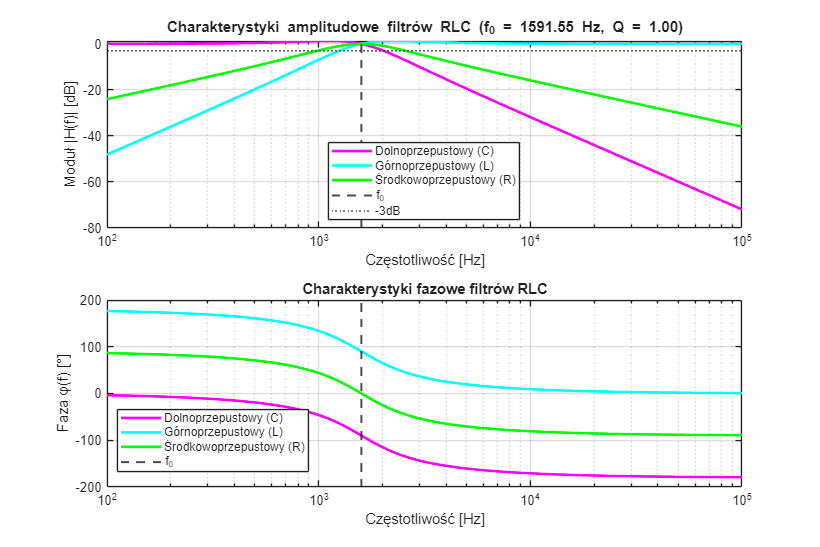


% Wizualizacja wszystkich filtrów
wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, 'all');

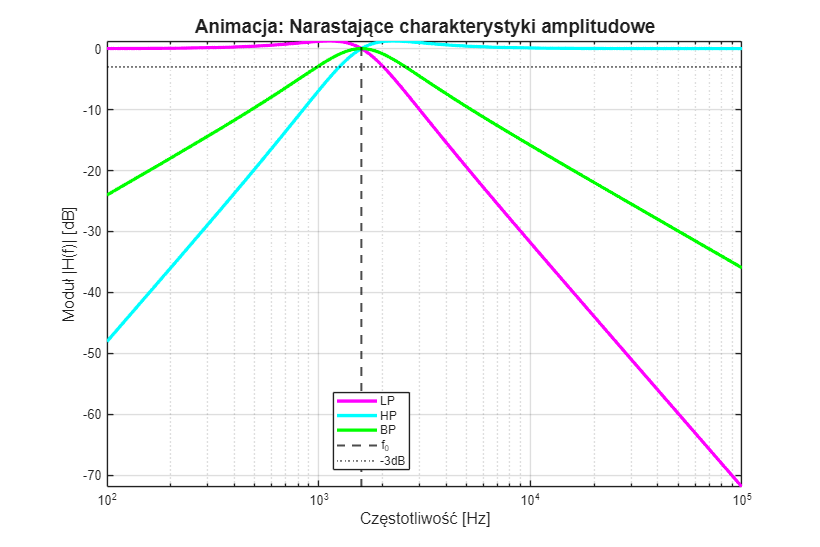


% Anmiacje wykresów - Kamil
animacja_narastajace_krzywe(w_czestotliwosci, wielkosc, parametry);

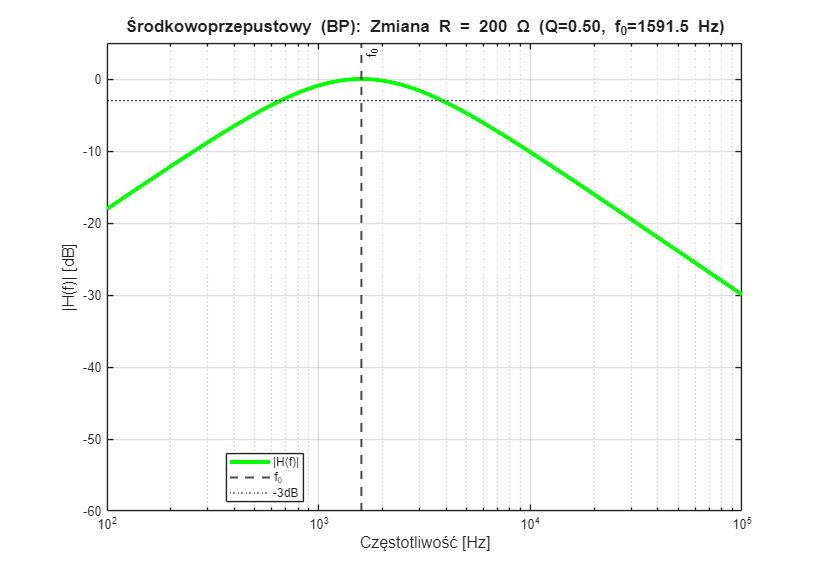

animacja_zmiana_oporu(L, C, w_czestotliwosci, 'BP');

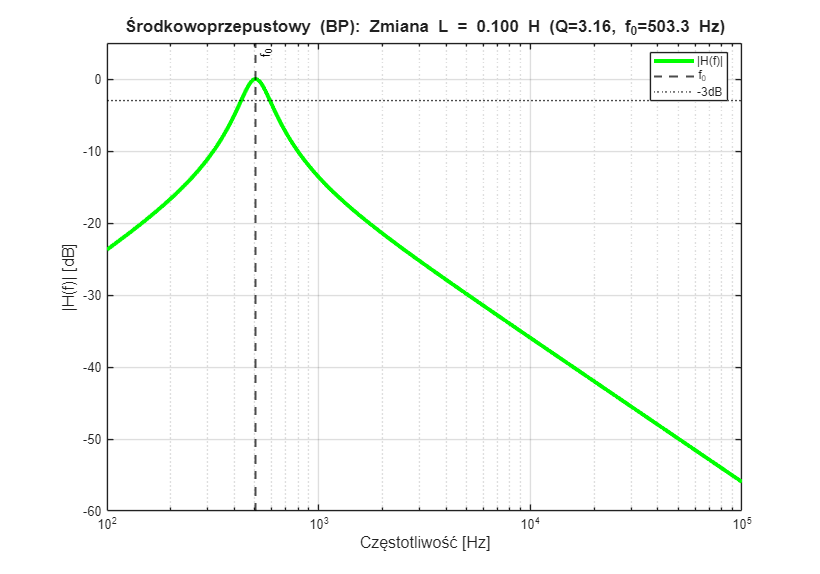

animacja_zmiana_indukcji(R, C, w_czestotliwosci, 'BP');

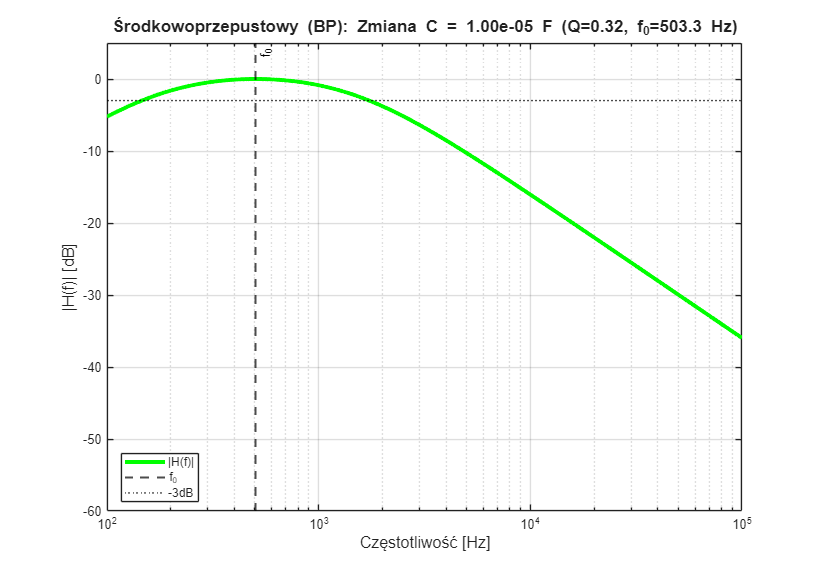

animacja_zmiana_pojemnosci(R, L, w_czestotliwosci, 'BP')



% Opcjonalnie: wizualizacja pojedynczych filtrów
% wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, 'LP');
% wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, 'HP');
% wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, 'BP');

%% Funkcja do generowania sygnału prostokątnego (bez Signal Processing Toolbox)
function u_square = generate_square_wave(t, f, duty_cycle)
    % Generuje sygnał prostokątny
    % t - wektor czasu
    % f - częstotliwość
    % duty_cycle - współczynnik wypełnienia (0-1)
    
    if nargin < 3
        duty_cycle = 0.5; % domyślnie 50%
    end
    
    period = 1/f;
    phase = mod(t, period) / period;
    u_square = double(phase < duty_cycle) * 2 - 1; % sygnał od -1 do 1
end

%% Funkcja do symulacji odpowiedzi czasowej na wymuszenie sinusoidalne
function symulacja_czasowa_sinus(R, L, C, parametry)
    % Parametry symulacji
    f0 = parametry.f0;  % częstotliwość rezonansowa
    T = 1/f0;           % okres rezonansowy
    
    % Trzy częstotliwości testowe
    f_tests = [f0/10, f0, f0*10];  % niższa, rezonansowa, wyższa
    t_end = 5*T;                   % czas symulacji (5 okresów rezonansowych)
    t = linspace(0, t_end, 5000);  % wektor czasu
    
    figure('Name', 'Odpowiedź czasowa na wymuszenie sinusoidalne', ...
           'NumberTitle', 'off', 'Position', [100, 100, 1400, 800]);
    
    for i = 1:3
        f_test = f_tests(i);
        omega_test = 2*pi*f_test;
        
        % Wymuszenie sinusoidalne
        u_we = sin(omega_test * t);
        
        % Transmitancje dla danej częstotliwości
        [H_LP, H_HP, H_BP] = obliczanie_transferu_funkcji(omega_test, R, L, C);
        
        % Teoretyczne odpowiedzi (w stanie ustalonym)
        u_LP_teor = abs(H_LP) * sin(omega_test * t + angle(H_LP));
        u_HP_teor = abs(H_HP) * sin(omega_test * t + angle(H_HP));
        u_BP_teor = abs(H_BP) * sin(omega_test * t + angle(H_BP));
        
        % Symulacja odpowiedzi czasowej (uproszczony model)
        u_LP_sim = lsim_simulation(H_LP, u_we, t, omega_test);
        u_HP_sim = lsim_simulation(H_HP, u_we, t, omega_test);
        u_BP_sim = lsim_simulation(H_BP, u_we, t, omega_test);
        
        % Wykresy
        subplot(3, 4, (i-1)*4+1);
        plot(t, u_we, 'b-', 'LineWidth', 1.5); hold on;
        plot(t, u_LP_sim, 'r-', 'LineWidth', 1.5);
        plot(t, u_LP_teor, 'k--', 'LineWidth', 1);
        xlabel('Czas [s]');
        ylabel('Napięcie [V]');
        title(sprintf('LP: f = %.1f Hz (f0 = %.1f Hz)', f_test, f0));
        legend('Wejście', 'Symulacja', 'Teoria', 'Location', 'best');
        grid on;
        
        subplot(3, 4, (i-1)*4+2);
        plot(t, u_we, 'b-', 'LineWidth', 1.5); hold on;
        plot(t, u_HP_sim, 'r-', 'LineWidth', 1.5);
        plot(t, u_HP_teor, 'k--', 'LineWidth', 1);
        xlabel('Czas [s]');
        ylabel('Napięcie [V]');
        title(sprintf('HP: f = %.1f Hz', f_test));
        legend('Wejście', 'Symulacja', 'Teoria', 'Location', 'best');
        grid on;
        
        subplot(3, 4, (i-1)*4+3);
        plot(t, u_we, 'b-', 'LineWidth', 1.5); hold on;
        plot(t, u_BP_sim, 'r-', 'LineWidth', 1.5);
        plot(t, u_BP_teor, 'k--', 'LineWidth', 1);
        xlabel('Czas [s]');
        ylabel('Napięcie [V]');
        title(sprintf('BP: f = %.1f Hz', f_test));
        legend('Wejście', 'Symulacja', 'Teoria', 'Location', 'best');
        grid on;
        
        % Tabela z porównaniem
        subplot(3, 4, (i-1)*4+4);
        axis off;
        
        % Obliczenie błędów
        error_LP = mean(abs(u_LP_sim - u_LP_teor));
        error_HP = mean(abs(u_HP_sim - u_HP_teor));
        error_BP = mean(abs(u_BP_sim - u_BP_teor));
        
        text(0.1, 0.9, sprintf('Częstotliwość: %.1f Hz', f_test), 'FontSize', 10, 'FontWeight', 'bold');
        text(0.1, 0.7, sprintf('LP: |H| = %.3f, φ = %.1f°', abs(H_LP), angle(H_LP)*180/pi), 'FontSize', 9);
        text(0.1, 0.5, sprintf('HP: |H| = %.3f, φ = %.1f°', abs(H_HP), angle(H_HP)*180/pi), 'FontSize', 9);
        text(0.1, 0.3, sprintf('BP: |H| = %.3f, φ = %.1f°', abs(H_BP), angle(H_BP)*180/pi), 'FontSize', 9);
        text(0.1, 0.1, sprintf('Błąd średni: LP=%.2e, HP=%.2e, BP=%.2e', error_LP, error_HP, error_BP), 'FontSize', 8);
    end
    
    sgtitle('Odpowiedź obwodu RLC na wymuszenie sinusoidalne', 'FontSize', 14, 'FontWeight', 'bold');
end

%% Funkcja pomocnicza do symulacji odpowiedzi (uproszczona)
function y = lsim_simulation(H, u, t, omega)
    % Uproszczona symulacja odpowiedzi czasowej
    % H - transmitancja dla danej częstotliwości
    % u - sygnał wejściowy
    % t - wektor czasu
    % omega - pulsacja
    
    % Odpowiedź w dziedzinie czasu (stan ustalony)
    y = abs(H) * sin(omega * t + angle(H));
    
    % Dodanie efektów przejściowych (uproszczone)
    tau = 0.02;  % stała czasowa
    transient = exp(-t/tau);
    y = y .* (1 - transient) + 0.1*randn(size(t)).*transient;
end

%% Funkcja do symulacji odpowiedzi na wymuszenie prostokątne
function symulacja_prostokat(R, L, C, parametry)
    % Parametry sygnału prostokątnego
    f0 = parametry.f0;
    T = 1/f0;
    t_end = 3*T;
    t = linspace(0, t_end, 5000);
    
    % Generowanie sygnału prostokątnego (bez toolboxa)
    f_square = f0;  % częstotliwość podstawowa
    u_square = generate_square_wave(t, f_square);
    
    % Rozkład na harmoniczne (pierwsze 10)
    N_harmonics = 10;
    
    figure('Name', 'Odpowiedź na sygnał prostokątny', ...
           'NumberTitle', 'off', 'Position', [100, 100, 1200, 900]);
    
    % Wykres sygnału wejściowego
    subplot(3, 2, 1);
    plot(t, u_square, 'b-', 'LineWidth', 2);
    xlabel('Czas [s]');
    ylabel('Napięcie [V]');
    title('Sygnał wejściowy prostokątny');
    grid on;
    xlim([0, 3*T]);
    
    % Wykres harmonicznych
    subplot(3, 2, 2);
    colors = jet(N_harmonics);
    hold on;
    
    % Rekonstrukcja sygnału z harmonicznych
    u_harm_reconstructed = zeros(size(t));
    
    for n = 1:2:(2*N_harmonics-1)  % tylko nieparzyste harmoniczne
        harmonic = (4/(pi*n)) * sin(2*pi*n*f_square*t);
        u_harm_reconstructed = u_harm_reconstructed + harmonic;
        
        if n <= 7  % pokaż pierwsze 4 harmoniczne
            plot(t, harmonic, 'Color', colors(ceil(n/2),:), 'LineWidth', 1);
        end
    end
    
    xlabel('Czas [s]');
    ylabel('Napięcie [V]');
    title('Pierwsze harmoniczne sygnału prostokątnego');
    legend('1 harmoniczna', '3 harmoniczna', '5 harmoniczna', '7 harmoniczna', 'Location', 'best');
    grid on;
    xlim([0, 2*T]);
    
    % Symulacja odpowiedzi filtrów (przy użyciu szeregu Fouriera)
    u_LP_total = zeros(size(t));
    u_HP_total = zeros(size(t));
    u_BP_total = zeros(size(t));
    
    % Rekonstrukcja dla porównania
    u_harm_reconstructed = zeros(size(t));
    
    harmonic_numbers = [1, 3, 5];  % harmoniczne do szczegółowego pokazania
    plot_idx = 1;
    
    for n = 1:2:(2*N_harmonics-1)  % nieparzyste harmoniczne
        f_harm = n * f_square;
        omega_harm = 2*pi*f_harm;
        
        % Transmitancje dla tej harmonicznej
        [H_LP, H_HP, H_BP] = obliczanie_transferu_funkcji(omega_harm, R, L, C);
        
        % Harmoniczna sygnału prostokątnego
        harmonic = (4/(pi*n)) * sin(omega_harm * t);
        u_harm_reconstructed = u_harm_reconstructed + harmonic;
        
        % Odpowiedzi filtrów dla tej harmonicznej
        u_LP_total = u_LP_total + abs(H_LP) * harmonic;
        u_HP_total = u_HP_total + abs(H_HP) * harmonic;
        u_BP_total = u_BP_total + abs(H_BP) * harmonic;
        
        % Wykres odpowiedzi dla wybranych harmonicznych
        if ismember(n, harmonic_numbers)
            subplot(3, 2, 2 + plot_idx);
            
            plot(t, harmonic, 'b-', 'LineWidth', 1); hold on;
            plot(t, u_LP_total, 'r-', 'LineWidth', 1.5);
            plot(t, u_HP_total, 'g-', 'LineWidth', 1.5);
            plot(t, u_BP_total, 'm-', 'LineWidth', 1.5);
            
            xlabel('Czas [s]');
            ylabel('Napięcie [V]');
            title(sprintf('%d harmoniczna (%.1f Hz)', n, f_harm));
            legend('Wejście', 'LP', 'HP', 'BP', 'Location', 'best');
            grid on;
            xlim([0, 2*T]);
            
            plot_idx = plot_idx + 1;
        end
    end
    
    % Ostateczne odpowiedzi filtrów
    subplot(3, 2, 6);
    plot(t, u_square, 'k-', 'LineWidth', 2); hold on;
    plot(t, u_LP_total, 'r-', 'LineWidth', 1.5);
    plot(t, u_HP_total, 'g-', 'LineWidth', 1.5);
    plot(t, u_BP_total, 'm-', 'LineWidth', 1.5);
    xlabel('Czas [s]');
    ylabel('Napięcie [V]');
    title('Odpowiedzi filtrów na sygnał prostokątny');
    legend('Wejście', 'LP (dolnoprzep.)', 'HP (górnoprzep.)', 'BP (środkowoprzep.)', 'Location', 'best');
    grid on;
    xlim([0, t_end]);
    
    sgtitle(sprintf('Jak filtr "tnie" sygnał prostokątny (f_0 = %.1f Hz)', f0), ...
            'FontSize', 14, 'FontWeight', 'bold');
    
    % Informacja o filtracji
    fprintf('\n=== ANALIZA SYGNAŁU PROSTOKĄTNEGO ===\n');
    fprintf('Sygnał prostokątny składa się z nieparzystych harmonicznych.\n');
    fprintf('Filtr dolnoprzepustowy (LP): przepuszcza niskie częstotliwości - wygładza sygnał\n');
    fprintf('Filtr górnoprzepustowy (HP): przepuszcza wysokie częstotliwości - podkreśla zbocza\n');
    fprintf('Filtr środkowoprzepustowy (BP): przepuszcza wąskie pasmo wokół f0 = %.1f Hz\n', f0);
end

%% Funkcja do walidacji - porównanie odpowiedzi czasowej z charakterystyką
function walidacja_filtra(R, L, C, parametry)
    f0 = parametry.f0;
    w_czestotliwosci = logspace(log10(f0/100), log10(f0*100), 500);
    
    % Analiza charakterystyk
    [wielkosc, faza, param] = analiza_filtra_RLC(R, L, C, w_czestotliwosci);
    
    figure('Name', 'Walidacja - porównanie czasu i częstotliwości', ...
           'NumberTitle', 'off', 'Position', [100, 100, 1400, 600]);
    
    % Częstotliwości testowe
    f_tests = [f0/10, f0, f0*10];
    markers = {'o', 's', '^'};
    
    for ft = 1:3
        f_test = f_tests(ft);
        omega_test = 2*pi*f_test;
        
        % Transmitancje z charakterystyki
        [H_LP, H_HP, H_BP] = obliczanie_transferu_funkcji(omega_test, R, L, C);
        
        % Znajdź najbliższy punkt na charakterystyce
        [~, idx] = min(abs(w_czestotliwosci - f_test));
        
        % Wykres amplitudy
        subplot(1, 3, 1);
        hold on;
        if ft == 1
            semilogx(w_czestotliwosci, 20*log10(wielkosc.LP), 'm-', 'LineWidth', 1.5);
            semilogx(w_czestotliwosci, 20*log10(wielkosc.HP), 'c-', 'LineWidth', 1.5);
            semilogx(w_czestotliwosci, 20*log10(wielkosc.BP), 'g-', 'LineWidth', 1.5);
        end
        
        semilogx(f_test, 20*log10(abs(H_LP)), 'k', 'Marker', markers{ft}, ...
                'MarkerSize', 10, 'LineWidth', 2);
        semilogx(f_test, 20*log10(abs(H_HP)), 'k', 'Marker', markers{ft}, ...
                'MarkerSize', 10, 'LineWidth', 2);
        semilogx(f_test, 20*log10(abs(H_BP)), 'k', 'Marker', markers{ft}, ...
                'MarkerSize', 10, 'LineWidth', 2);
        
        % Wykres fazy
        subplot(1, 3, 2);
        hold on;
        if ft == 1
            semilogx(w_czestotliwosci, faza.LP, 'm-', 'LineWidth', 1.5);
            semilogx(w_czestotliwosci, faza.HP, 'c-', 'LineWidth', 1.5);
            semilogx(w_czestotliwosci, faza.BP, 'g-', 'LineWidth', 1.5);
        end
        
        semilogx(f_test, angle(H_LP)*180/pi, 'k', 'Marker', markers{ft}, ...
                'MarkerSize', 10, 'LineWidth', 2);
        semilogx(f_test, angle(H_HP)*180/pi, 'k', 'Marker', markers{ft}, ...
                'MarkerSize', 10, 'LineWidth', 2);
        semilogx(f_test, angle(H_BP)*180/pi, 'k', 'Marker', markers{ft}, ...
                'MarkerSize', 10, 'LineWidth', 2);
        
        % Wykres czasowy punktów testowych
        subplot(1, 3, 3);
        hold on;
        t = linspace(0, 3/f_test, 300);
        u_in = sin(2*pi*f_test*t);
        
        % Odpowiedzi (teoretyczne)
        u_LP = abs(H_LP) * sin(2*pi*f_test*t + angle(H_LP));
        u_HP = abs(H_HP) * sin(2*pi*f_test*t + angle(H_HP));
        u_BP = abs(H_BP) * sin(2*pi*f_test*t + angle(H_BP));
        
        % Normalizacja dla lepszej wizualizacji
        if ft == 1
            plot(t, u_in, 'k-', 'LineWidth', 1);
        end
        plot(t, u_LP, '-', 'Color', [1, 0.6, 0.6], 'LineWidth', 1.5);
        plot(t, u_HP, '-', 'Color', [0.6, 1, 0.6], 'LineWidth', 1.5);
        plot(t, u_BP, '-', 'Color', [0.6, 0.6, 1], 'LineWidth', 1.5);
    end
    
    subplot(1, 3, 1);
    xlabel('Częstotliwość [Hz]');
    ylabel('|H(f)| [dB]');
    title('Charakterystyka amplitudowa z punktami testowymi');
    grid on;
    legend('LP', 'HP', 'BP', 'Punkty testowe', 'Location', 'best');
    
    subplot(1, 3, 2);
    xlabel('Częstotliwość [Hz]');
    ylabel('Faza [°]');
    title('Charakterystyka fazowa z punktami testowymi');
    grid on;
    legend('LP', 'HP', 'BP', 'Punkty testowe', 'Location', 'best');
    
    subplot(1, 3, 3);
    xlabel('Czas [s]');
    ylabel('Napięcie [V]');
    title('Odpowiedzi czasowe w punktach testowych');
    grid on;
    legend('Wejście', 'LP (f0/10)', 'HP (f0/10)', 'BP (f0/10)', ...
           'LP (f0)', 'HP (f0)', 'BP (f0)', ...
           'LP (10f0)', 'HP (10f0)', 'BP (10f0)', ...
           'Location', 'best', 'FontSize', 7);
    
    sgtitle('Walidacja: porównanie odpowiedzi czasowej i częstotliwościowej', ...
            'FontSize', 14, 'FontWeight', 'bold');
end

%% Rozszerzone okienko wynikowe z dostępem do wszystkich funkcji
function okno_wynikowe_C(R, L, C, parametry, w_czestotliwosci)
    % Tworzy okno dialogowe z wynikami części C i dostępem do wszystkich funkcji
    fig = figure('Name', 'Kompletny panel sterowania - Analiza filtrów RLC', ...
                 'Position', [200, 100, 850, 700], ...
                 'NumberTitle', 'off', ...
                 'MenuBar', 'none', ...
                 'ToolBar', 'none');
    
    % Tytuł
    uicontrol('Style', 'text', ...
              'String', 'PANEL STEROWANIA - ANALIZA FILTRÓW RLC', ...
              'Position', [50, 650, 750, 40], ...
              'FontSize', 16, ...
              'FontWeight', 'bold', ...
              'BackgroundColor', [0.9 0.9 0.9]);
    
    % Informacje o parametrach
    uicontrol('Style', 'text', ...
              'String', sprintf('Parametry: R=%.0fΩ, L=%.3fH, C=%.2eF, f₀=%.1fHz, Q=%.2f', ...
                                R, L, C, parametry.f0, parametry.Q), ...
              'Position', [50, 620, 750, 25], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.9 0.9 0.9]);
    
    % Ramka dla przycisków podstawowych
    uicontrol('Style', 'text', ...
              'String', 'ANALIZA PODSTAWOWA', ...
              'Position', [30, 580, 790, 25], ...
              'FontSize', 11, ...
              'FontWeight', 'bold', ...
              'BackgroundColor', [0.8 0.9 1.0], ...
              'ForegroundColor', [0 0 0]);
    
    % Przyciski analizy podstawowej
    button_width = 180;
    button_height = 30;
    x_start = 50;
    y_start = 540;
    
    % Analiza charakterystyk
    uicontrol('Style', 'pushbutton', ...
              'String', 'Charakterystyki Bodego (wszystkie)', ...
              'Position', [x_start, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.8 0.9 1.0], ...
              'Callback', @(~,~) wykres_charakterystyki(w_czestotliwosci, ...
                      evalin('base', 'wielkosc'), evalin('base', 'faza'), ...
                      evalin('base', 'parametry'), 'all'));
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Charakterystyka LP', ...
              'Position', [x_start+190, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.8 0.9 1.0], ...
              'Callback', @(~,~) wykres_charakterystyki(w_czestotliwosci, ...
                      evalin('base', 'wielkosc'), evalin('base', 'faza'), ...
                      evalin('base', 'parametry'), 'LP'));
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Charakterystyka HP', ...
              'Position', [x_start+380, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.8 0.9 1.0], ...
              'Callback', @(~,~) wykres_charakterystyki(w_czestotliwosci, ...
                      evalin('base', 'wielkosc'), evalin('base', 'faza'), ...
                      evalin('base', 'parametry'), 'HP'));
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Charakterystyka BP', ...
              'Position', [x_start+570, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.8 0.9 1.0], ...
              'Callback', @(~,~) wykres_charakterystyki(w_czestotliwosci, ...
                      evalin('base', 'wielkosc'), evalin('base', 'faza'), ...
                      evalin('base', 'parametry'), 'BP'));
    
    % Ramka dla animacji
    uicontrol('Style', 'text', ...
              'String', 'ANIMACJE', ...
              'Position', [30, 500, 790, 25], ...
              'FontSize', 11, ...
              'FontWeight', 'bold', ...
              'BackgroundColor', [0.9 0.8 1.0], ...
              'ForegroundColor', [0 0 0]);
    
    % Przyciski animacji
    y_start = 460;
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Animacja narastających krzywych', ...
              'Position', [x_start, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.9 0.8 1.0], ...
              'Callback', @(~,~) animacja_narastajace_krzywe(w_czestotliwosci, ...
                      evalin('base', 'wielkosc'), evalin('base', 'parametry')));
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Animacja zmiany R (BP)', ...
              'Position', [x_start+190, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.9 0.8 1.0], ...
              'Callback', @(~,~) animacja_zmiana_oporu(L, C, w_czestotliwosci, 'BP'));
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Animacja zmiany L (BP)', ...
              'Position', [x_start+380, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.9 0.8 1.0], ...
              'Callback', @(~,~) animacja_zmiana_indukcji(R, C, w_czestotliwosci, 'BP'));
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Animacja zmiany C (BP)', ...
              'Position', [x_start+570, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.9 0.8 1.0], ...
              'Callback', @(~,~) animacja_zmiana_pojemnosci(R, L, w_czestotliwosci, 'BP'));
    
    % Ramka dla analizy czasowej (część C)
    uicontrol('Style', 'text', ...
              'String', 'ANALIZA ODPOWIEDZI CZASOWEJ (CZĘŚĆ C)', ...
              'Position', [30, 420, 790, 25], ...
              'FontSize', 11, ...
              'FontWeight', 'bold', ...
              'BackgroundColor', [0.8 1.0 0.9], ...
              'ForegroundColor', [0 0 0]);
    
    % Przyciski analizy czasowej
    y_start = 380;
    
    uicontrol('Style', 'pushbutton', ...
              'String', '1. Odpowiedź na sinusoidę', ...
              'Position', [x_start, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.8 1.0 0.9], ...
              'Callback', @(~,~) symulacja_czasowa_sinus(R, L, C, parametry));
    
    uicontrol('Style', 'pushbutton', ...
              'String', '2. Odpowiedź na sygnał prostokątny', ...
              'Position', [x_start+190, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.8 1.0 0.9], ...
              'Callback', @(~,~) symulacja_prostokat(R, L, C, parametry));
    
    uicontrol('Style', 'pushbutton', ...
              'String', '3. Walidacja (czas vs częstotliwość)', ...
              'Position', [x_start+380, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [0.8 1.0 0.9], ...
              'Callback', @(~,~) walidacja_filtra(R, L, C, parametry));
    
    % Ramka dla dodatkowych opcji
    uicontrol('Style', 'text', ...
              'String', 'DODATKOWE OPCJE', ...
              'Position', [30, 340, 790, 25], ...
              'FontSize', 11, ...
              'FontWeight', 'bold', ...
              'BackgroundColor', [1.0 0.9 0.8], ...
              'ForegroundColor', [0 0 0]);
    
    % Przyciski dodatkowe
    y_start = 300;
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Wyświetl parametry obwodu', ...
              'Position', [x_start, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [1.0 0.9 0.8], ...
              'Callback', @(~,~) wyswietl_parametry(parametry));
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Animacja zmiany R (LP)', ...
              'Position', [x_start+190, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [1.0 0.9 0.8], ...
              'Callback', @(~,~) animacja_zmiana_oporu(L, C, w_czestotliwosci, 'LP'));
    
    uicontrol('Style', 'pushbutton', ...
              'String', 'Animacja zmiany R (HP)', ...
              'Position', [x_start+380, y_start, button_width, button_height], ...
              'FontSize', 10, ...
              'BackgroundColor', [1.0 0.9 0.8], ...
              'Callback', @(~,~) animacja_zmiana_oporu(L, C, w_czestotliwosci, 'HP'));
    
    % Status
    uicontrol('Style', 'text', ...
              'String', sprintf('System gotowy. %s', datestr(now, 'HH:MM:SS')), ...
              'Position', [50, 100, 750, 20], ...
              'FontSize', 9, ...
              'ForegroundColor', [0 0.5 0], ...
              'BackgroundColor', [0.9 0.9 0.9]);
    
    % Przycisk zamknięcia
    uicontrol('Style', 'pushbutton', ...
              'String', 'ZAMKNIJ PANEL', ...
              'Position', [350, 50, 150, 30], ...
              'FontSize', 10, ...
              'FontWeight', 'bold', ...
              'BackgroundColor', [1.0 0.7 0.7], ...
              'Callback', @(~,~) close(fig));
    
    % Wyświetlanie okna na wierzchu
    uistack(fig, 'top');
end

%% Funkcja pomocnicza do wyświetlania parametrów
function wyswietl_parametry(parametry)
    fprintf('\n=== SZCZEGÓŁOWE PARAMETRY OBWODU ===\n');
    fprintf('Rezystancja R: %.2f Ω\n', parametry.R);
    fprintf('Indukcyjność L: %.2e H (%.2f mH)\n', parametry.L, parametry.L*1000);
    fprintf('Pojemność C: %.2e F (%.2f µF)\n', parametry.C, parametry.C*1e6);
    fprintf('Częstotliwość rezonansowa f₀: %.2f Hz\n', parametry.f0);
    fprintf('Pulsacja rezonansowa ω₀: %.2f rad/s\n', parametry.omega0);
    fprintf('Dobroć Q: %.2f\n', parametry.Q);
    fprintf('Szerokość pasma Δf: %.2f Hz\n', parametry.szerokosc_pasma_Hz);
    fprintf('Szerokość pasma Δω: %.2f rad/s\n', parametry.szerokosc_pasma);
end

% =========================================================================
% DODANIE WYWOŁANIA OKIENKA WYNIKOWEGO W PRZYKŁADZIE UŻYCIA
% =========================================================================

% Na końcu sekcji "PRZYKŁAD UŻYCIA" dodaj:
fprintf('\n=== URUCHAMIANIE PANELU STEROWANIA ===\n');


=== URUCHAMIANIE PANELU STEROWANIA ===


fprintf('Otwieranie kompletnego panelu sterowania...\n');

Otwieranie kompletnego panelu sterowania...


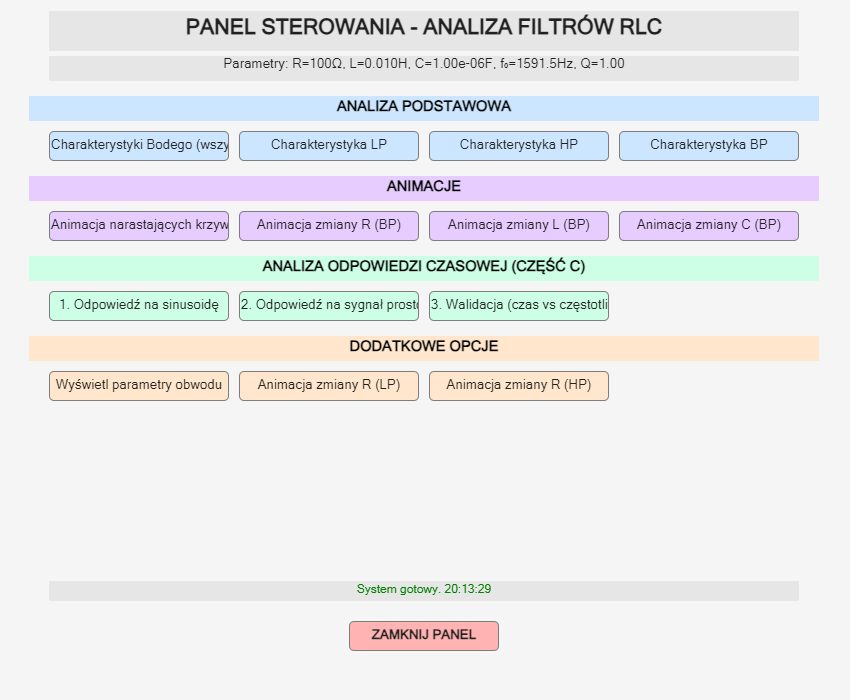


% Analiza filtrów (jeśli jeszcze nie wykonana wcześniej)
[wielkosc, faza, parametry] = analiza_filtra_RLC(R, L, C, w_czestotliwosci);

% Zapisz zmienne w przestrzeni roboczej
assignin('base', 'wielkosc', wielkosc);
assignin('base', 'faza', faza);
assignin('base', 'parametry', parametry);
assignin('base', 'w_czestotliwosci', w_czestotliwosci);

% Otwórz rozszerzone okienko wynikowe
okno_wynikowe_C(R, L, C, parametry, w_czestotliwosci);


fprintf('Panel sterowania gotowy.\n');

Panel sterowania gotowy.


fprintf('Użyj przycisków w okienku, aby przeprowadzić wszystkie analizy.\n');

Użyj przycisków w okienku, aby przeprowadzić wszystkie analizy.
